# Space Time Adaptive Processing (STAP) Lab

In this lab, we demonstrate an MVDR based STAP algorithm, which is often used as a benchmark for other STAP algorithms. We will look at how clutter and jammers manifest themselves in space-time, i.e., angle-Doppler domain and how STAP technique allows us to filter out these undesired returns.

## Setup Radar Parameters

Let us first set up the radar. Using Phaser as an example, assume the radar is working at 10 GHz with an 8-element ULA of half-wavelength spacing. 

c = 3e8;
fc = 10e9;
lambda = c/fc;

N = 8;
d = lambda/2;
ant = phased.ULA(N,d);


## Setup Doppler Parameters

The Doppler processing happens in slow time. Assume the Doppler processing is performed with a 64-pulse coherent processing interval (CPI). The PRF is 2 kHz, and the sample rate is 5 MHz. The radar is side-looking and is moving at a speed so that the radar travels one element spacing during one pulse.

Np = 64;

prf = 2e3;
fs = 5e6;
v = d*prf;

## Signal Return

Assume we have signal at boresight and is moving at 200 m/s.

adresp = phased.AngleDopplerResponse('SensorArray',ant,...
    'OperatingFrequency',fc,'PRF',prf,'NumDopplerSamples',Np,...
    'NumAngleSamples',181);

angd = 0;
dopd = 200;

The steering vector in the angle-Doppler domain is computed via a Kronecker product of an angular domain steering vector and a Doppler domain steering vector.

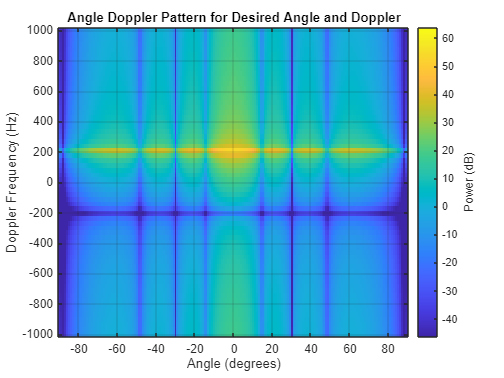

SV = phased.SteeringVector('SensorArray',ant,'PropagationSpeed',c);
Tapa = rectwin(N);
Wat = SV(fc,angd).*Tapa;
Tapd = rectwin(Np);
Wdt = dopsteeringvec(dopd,Np,prf).*Tapd;
sigmat = 1;
Wstt = sqrt(sigmat)*kron(Wdt,Wat);

plotResponse(adresp,Wstt);
title('Angle Doppler Pattern for Desired Angle and Doppler')

## Clutter Return

For a GMTI radar, clutter is the echo from the ground surface. It comes from all around the radar. For a monostatic radar, each range gate corresponds to a ring on the ground. Think about that ring is divided into many small patches. In this lab, we divide the ring into 360 patches, one degree a piece. Each patch has its corresponding angular domain steering vector.

angc = -180:180;
Wacmat = SV(fc,angc).*Tapa;

Meanwhile, Doppler is given by the relative radial speed between each clutter patch and the radar. Through geometry, it can be shown that the Doppler for each clutter patch, in this case, is related to the direction of that patch.

dopc = v.*sind(angc)/lambda;
Wadmat = dopsteeringvec(dopc,Np,prf).*Tapd;

The space-time steering vector can then be computed for each patch. Note that due to the substantial number of patches, the return of the clutter is much stronger than the target echo.

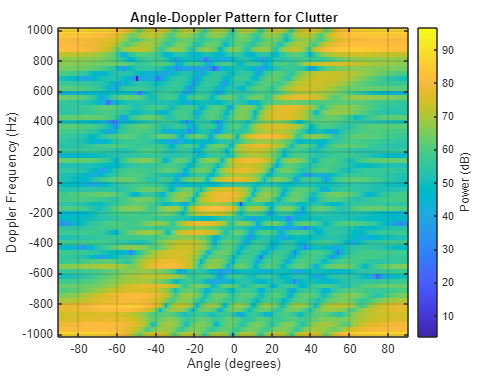

Nc = size(angc,2);
Wstcmat = zeros(size(Wstt,1),Nc,'like',1i);
sigmac = 50;
for m = 1:Nc
    Wstcmat(:,m) = sqrt(sigmac/2)*(randn+1i*randn)*kron(Wadmat(:,m),Wacmat(:,m));
end

Wstc = sum(Wstcmat,2);
plotResponse(adresp,Wstc);
title('Angle-Doppler Pattern for Clutter')

## Jammer Return 

Jammer normally comes from a certain direction and presents in all Doppler bins. This lab assumes that the jammer is at 50 degrees azimuth. Jammer signal is normally also stronger than the target because the jammer signal only goes through one way propagation.

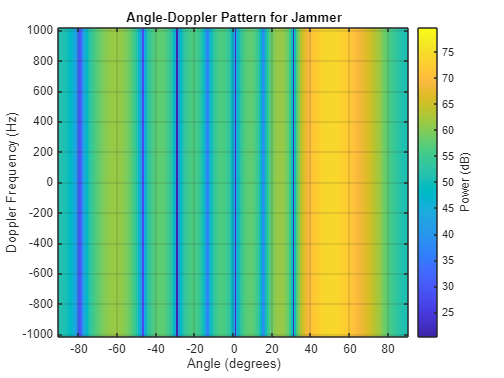

angj = 50;
Waj = SV(fc,angj).*Tapa;
dopj = (0:Np-1)*prf/Np-prf/2;
Wdjmat = dopsteeringvec(dopj,Np,prf).*Tapd;
Wstjmat = zeros(size(Wstt,1),Np,'like',1i);
sigmaj = 100;
for m = 1:Np
    Wstjmat(:,m) = sqrt(sigmaj)*kron(Wdjmat(:,m),Waj);
end
Wstj = sum(Wstjmat,2);
plotResponse(adresp,Wstj);
title('Angle-Doppler Pattern for Jammer');

## Total Return Model

The total signal is a combination of all returns. Notice that the return in the angle-Doppler domain is dominated by the clutter and jammer.

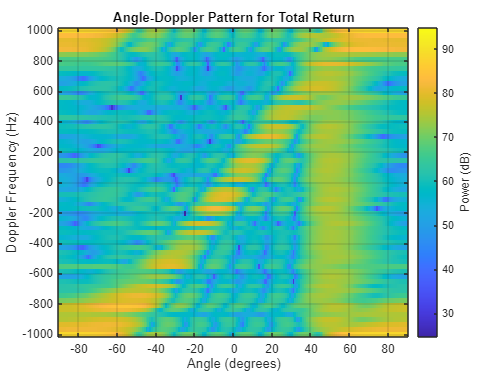

plotResponse(adresp,Wstt+Wstc+Wstj);
title('Angle-Doppler Pattern for Total Return')

## STAP Weights

The weights for STAP are computed in the same fashion as the MVDR weights, only in the space time domain. The response of in the angle-Doppler domain shows that the weights successfully filtered out the clutter and the jammer.

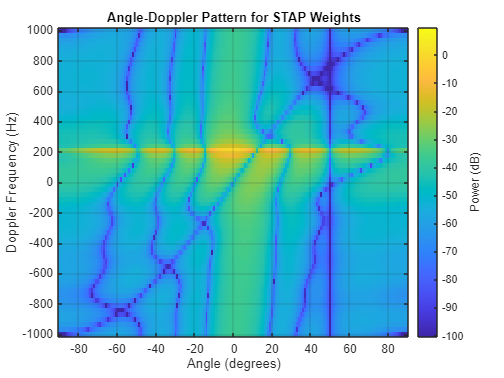

sigman = 0.01;
Rn = sigman*eye(size(Wstt,1))+(Wstcmat*Wstcmat')+(Wstjmat*Wstjmat');
Wstap = (Rn\Wstt)/(Wstt'*(Rn\Wstt));
plotResponse(adresp,Wstap);
title('Angle-Doppler Pattern for STAP Weights')